**标准化河流梯度指数（SLK, Standardized stream-length gradient index）**

Hack（1973）通过“坡降指数（SL）”来定量描述河流纵向坡度的变化与地表侵蚀、沉降过程之间变化关系。它是指单位距离的坡度与该段河流到源头距离的乘积，其计算公式为：


$$\textrm{SL}=\left(\frac{\Delta H}{\Delta L}\right)\times L$$


式中，$\Delta \;H$ 代表河流源头与出口之间的高差，$\Delta \;L$ 代表河流源头至出口之间的平距，$L$ 为该段河流距离源头的距离，$\frac{\Delta H}{\Delta L}$为单位距离的坡度。用均衡值 $K$ 对坡降指数（$\textrm{SL}$）值标准化处理得到 $\textrm{SLK}$ 指数，用以比较不同长度河道的活动性计算公式为：


$$K=\frac{H_{\textrm{total}} }{\ln \left(L_{\textrm{total}} \right)}$$



$$\textrm{SLK}=\frac{\textrm{SL}}{K}$$


式中，$H_{\textrm{total}}$ 代表河流源头与出口之间的高差，$L_{\textrm{total}}$ 代表河流源头至出口的总长度。将各段河流的 $\textrm{SLK}$ 值进行算术平均，可得到整个流域的 $\textrm{SLK}$ 的平均值。


$${\textrm{SLK}}_{\textrm{avg}} =\frac{\sum_{\;} \textrm{SLK}}{n}$$


式中，$\sum \textrm{SLK}$ 为河流各段 $\textrm{SLK}$ 值之和，n 代表河流数量。

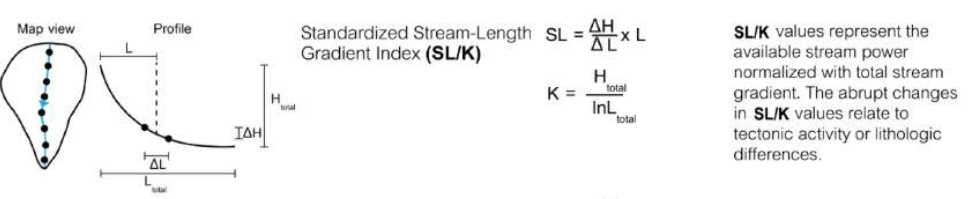

SLK值可分为三类：SLK值>3.7、2.5-3.7和<2.5分别被分为构造活动、轻微活动和不活动或稳定（El Hamdouni等人，2008年）。

function SLK_index = ttb_calculate_slk_index(dem, main_stream)
    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);
    stream_segment_num = length(main_stream_x) - 2; % main_stream 线段最后一个坐标点为 NaN

    % 计算 total_delta_h 和 total_delta_l
    total_delta_h = get_elevation(dem, main_stream_x(1), main_stream_y(1)) - ...
              get_elevation(dem, main_stream_x(end-1), main_stream_y(end-1));
    total_delta_l = 0;
    for i = 1 : stream_segment_num
        total_delta_l = total_delta_l + get_distance( ...
            main_stream_x(i), main_stream_y(i), ...
            main_stream_x(i + 1), main_stream_y(i) ...
        );
    end

    % 计算 SL 值
    sl_value = zeros(stream_segment_num, 1);
    length_from_source = 0;
    pre_mid_point = [main_stream_x(1), main_stream_y(1)];
    for i = 1 : stream_segment_num
        % 线段中点坐标
        cur_mid_point = [(main_stream_x(i+1) + main_stream_x(i)) / 2, ...
                     (main_stream_y(i+1) + main_stream_y(i)) / 2];
        
        % 计算每个河段到源头点的距离
        length_from_source = length_from_source + get_distance( ...
            pre_mid_point(1), pre_mid_point(2), cur_mid_point(1), cur_mid_point(2) ...
        );
        pre_mid_point = cur_mid_point;

        % 局部高差
        delta_h = get_elevation(dem, main_stream_x(i), main_stream_y(i)) - ...
                  get_elevation(dem, main_stream_x(i+1), main_stream_y(i+1));

        % 局部距离
        delta_l = get_distance(main_stream_x(i), main_stream_y(i), ...
                               main_stream_x(i+1), main_stream_y(i+1));

        % 计算 SL 值
        sl_value(i) = delta_h / delta_l * length_from_source;
    end

    % 计算均衡值 K
    k_value = total_delta_h / log(total_delta_l);

    SLK_index = mean(sl_value) / k_value;
end


function elevation = get_elevation(dem, x, y)
    % 通过流域多边形边界得到的坐标转换为栅格二维矩阵下标的时候可能存在误差
    % 因此此处在找不到有效值的时候搜索临近像素去获取高程值
    [row, col] = dem.coord2sub(x, y);
    if ~isnan(dem.Z(row, col))
        elevation = dem.Z(row, col);
        return;
    end
    direction = [[1, 0]; [-1, 0]; [0, 1]; [0, -1]];
    queue = [row, col];
    visited = false(dem.size);
    visited(row, col) = true;
    while ~isempty(queue)
        [row, col] = queue(1);
        queue(1) = [];
        for i = 1 : 4
            next_row = row + direction(i, 1);
            next_col = col + direction(i, 2);
            if next_row < 1 || next_row > dem.size(1) || ...
                next_col < 1 || next_col > dem.size(2) || ...
                visited(next_row, next_col)
                continue;
            end
            if ~isnan(dem.Z(next_row, next_col))
                elevation = dem.Z(next_row, next_col);
                return;
            end
            queue = [queue; [next_row, next_col]];
            visited(next_row, next_col) = true;
        end
    end
    elevation = NaN;
end

function distance = get_distance(x1, y1, x2, y2)
    distance = sqrt((x2 - x1) ^ 2 + (y2 - y1) ^ 2);
end